## EE634 HW3

## Kutay Ugurlu

### Q1

#### The HSI-RGB and RGB-HSI color conversion formulas are from [here.](https://www.had2know.org/technology/hsi-rgb-color-converter-equations.html#:~:text=Equations%20to%20Convert%20RGB%20Values%20to%20HSI%20Values&text=I%20%3D%20(R%20%2B%20G%20%2B%20B)%2F3.)

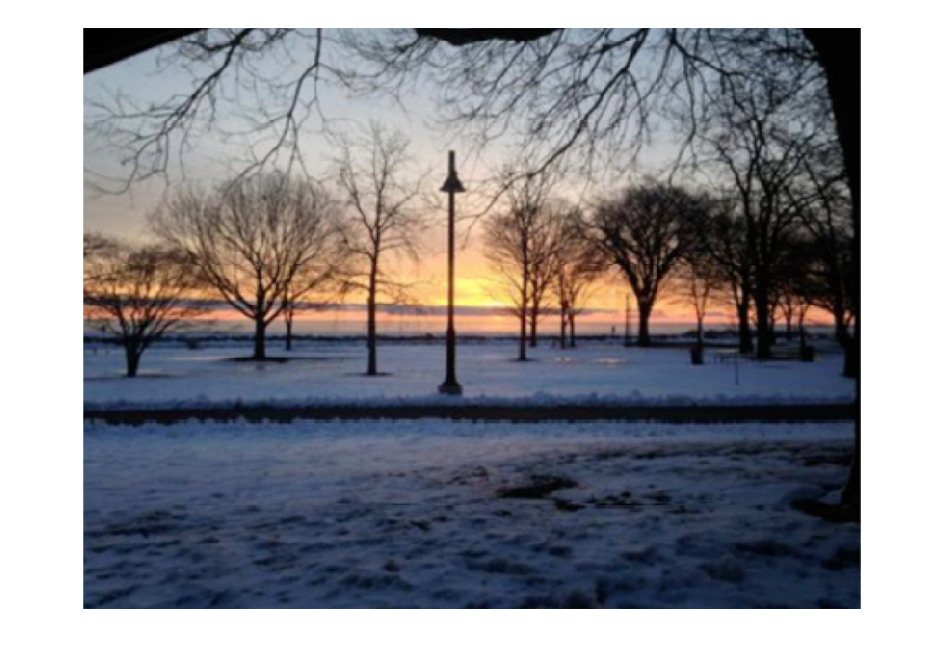

rgb = imread("colorImage.png");
figure
imshow(rgb)

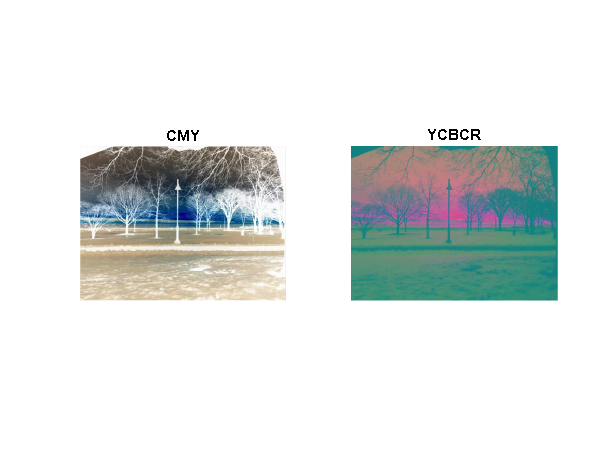

cmy = 255 - rgb; 
ycbcr = rgb2ycbcr(rgb);
figure
subplot(1,2,1)
imshow(cmy)
title("CMY")
subplot(1,2,2)
imshow(ycbcr)
title("YCBCR")

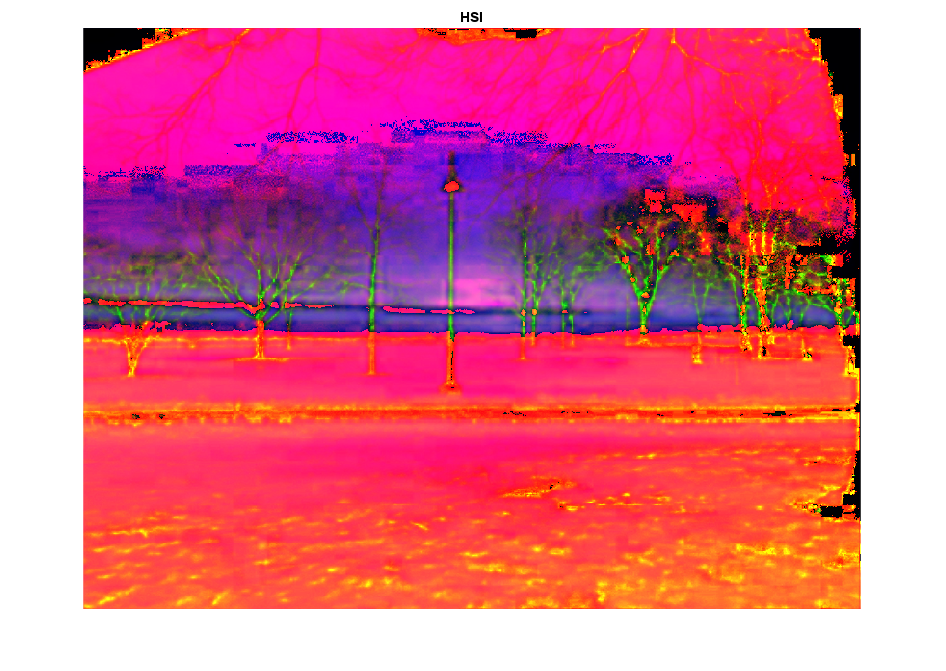

drgb = im2double(rgb);
R = drgb(:,:,1) ; G = drgb(:,:,2) ; B = drgb(:,:,3);
I = mean(drgb,3);
S = 1 - min(drgb,[],3)./I; S(I==0) = 0;
H = acos((R-0.5*G-0.5*B)./sqrt(R.^2+G.^2+B.^2-R.*G-R.*B-G.*B));
H(isnan(H)) = 0;
H(B>G) = 2*pi - H(B>G);
hsi = real(cat(3,H,S,I));
figure
imshow(hsi); title("HSI")

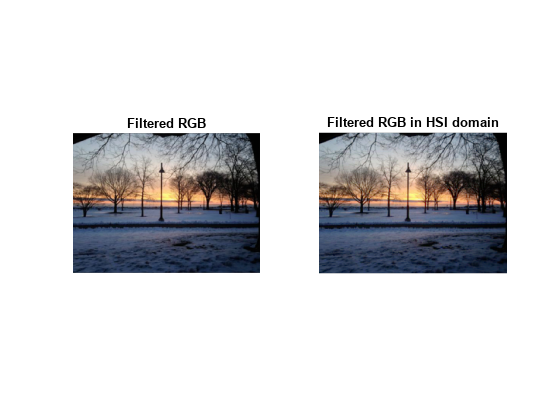

blur_filter = 1/25 * ones(5,5);
filt_r = conv2(R,blur_filter,"same");
filt_g = conv2(G,blur_filter,"same");
filt_b = conv2(B,blur_filter,"same");
filtered_RGB = cat(3,filt_r,filt_g,filt_b);

dhsi = double(hsi);
I = dhsi(:,:,end);
filt_I = conv2(I,blur_filter,"same");
dhsi(:,:,end) = filt_I;
filtered_HSI = dhsi;

H = filtered_HSI(:,:,1);
S = filtered_HSI(:,:,2);
I = filtered_HSI(:,:,3);

R_back = zeros(size(filt_I));
G_back = R_back;
B_back = G_back;

cond = (H==0 | H==2*pi);
R_back(cond) = I(cond) + 2*I(cond).*S(cond);
G_back(cond) = I(cond) - I(cond).*S(cond);
B_back(cond) = I(cond) - I(cond).*S(cond);

cond = (H>0 & H<2*pi/3);
R_back(cond) = I(cond) + I(cond).*S(cond).*cos(H(cond))./cos(pi/3-H(cond));
G_back(cond) = I(cond) + I(cond).*S(cond).*(1 - cos(H(cond))./cos(pi/3-H(cond)));
B_back(cond) = I(cond) - I(cond).*S(cond);

cond = (H==2*pi/3);
R_back(cond) = I(cond) - I(cond).*S(cond);
G_back(cond) = I(cond) + 2*I(cond).*S(cond);
B_back(cond) = I(cond) - I(cond).*S(cond);

cond = (H>2*pi/3 & H<4*pi/3);
R_back(cond) = I(cond) - I(cond).*S(cond);
G_back(cond) = I(cond) + I(cond).*S(cond).*cos(H(cond)-2*pi/3)./cos(pi-H(cond));
B_back(cond) = I(cond) + I(cond).*S(cond).*(1 - cos(H(cond)-2*pi/3)./cos(pi-H(cond)));

cond = (H==4*pi/3);
R_back(cond) = I(cond) - I(cond).*S(cond);
G_back(cond) = I(cond) - I(cond).*S(cond);
B_back(cond) = I(cond) + 2*I(cond).*S(cond);

cond = (H>4*pi/3 & H<2*pi);
R_back(cond) = I(cond) + I(cond).*S(cond).*(1 - cos(H(cond)-4*pi/3)./cos(5*pi/3-H(cond)));
G_back(cond) = I(cond) - I(cond).*S(cond);
B_back(cond) = I(cond) + I(cond).*S(cond).*cos(H(cond)-4*pi/3)./cos(5*pi/3-H(cond));

rgb_back = cat(3,R_back,G_back,B_back);
figure
subplot(1,2,1)
imshow(filtered_RGB)
title("Filtered RGB")
subplot(1,2,2)
imshow(rgb_back)
title("Filtered RGB in HSI domain")

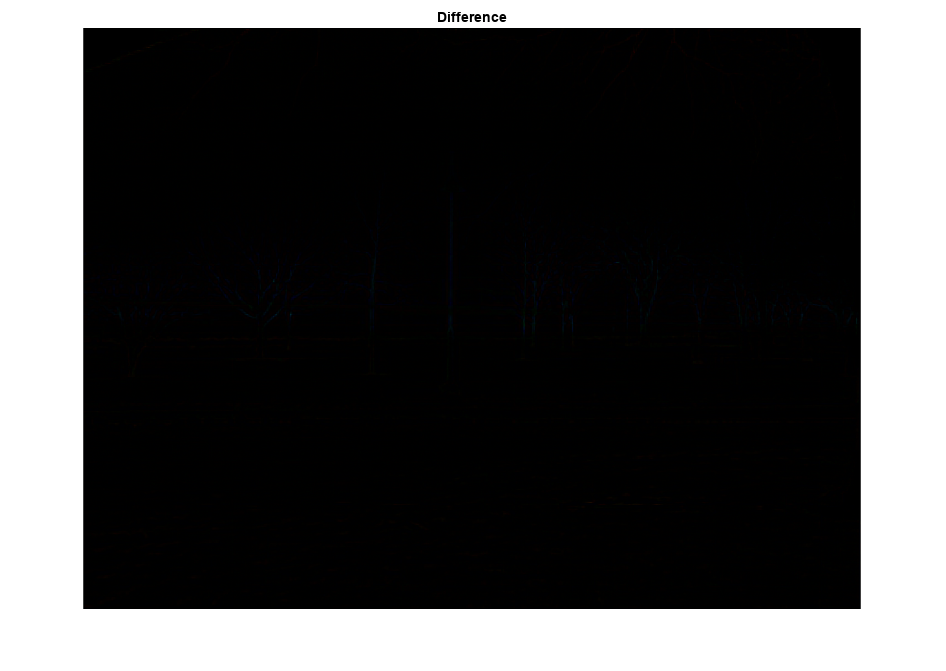

figure
imshow(filtered_RGB-rgb_back)
title('Difference')

### Q2

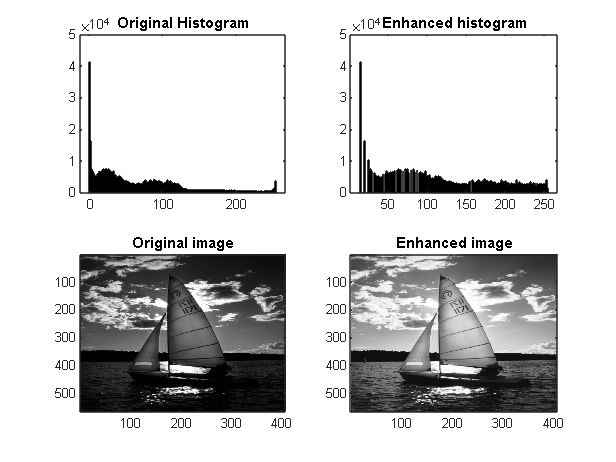

dark = imread("darkImage.png");
dark_enhanced = zeros(size(dark));
values = histcounts(dark,256);
N = numel(dark);
for i = 0:255
    v = 255/N*sum(values(1:i+1));
    dark_enhanced(dark==i) = round(v);
end
figure
subplot(2,2,1)
h = histogram(dark,255);
title('Original Histogram')
subplot(2,2,2)
h2 = histogram(dark_enhanced,255);
title("Enhanced histogram")
subplot(2,2,3)
imagesc(dark);
colormap gray
title('Original image')
subplot(2,2,4)
imagesc(uint8(dark_enhanced));
colormap gray
title('Enhanced image')

### Q3

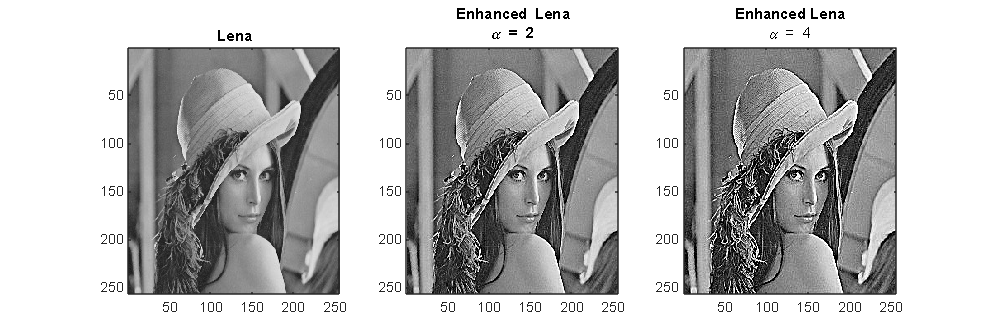

lena = mat2gray(im2double(imread("8-bit-256-x-256-Grayscale-Lena-Image.jpeg")));
lena_low = imgaussfilt(lena,1); % Smoother image with gaussian filter of std 1
alpha = 2;
unsharp_mask = lena - lena_low;
enhanced = lena + alpha*unsharp_mask;
alpha = 4;
enhanced2 = lena + alpha*unsharp_mask;

figure('Position', [10 10 900 300]);
subplot(1,3,1);
imagesc(lena)
colormap gray;
title("Lena")
subplot(1,3,2);
imagesc(enhanced);
colormap gray;
title({"Enhanced Lena","\alpha = 2"})
subplot(1,3,3);
imagesc(enhanced2);
colormap gray;
title({"Enhanced Lena"},"\alpha = 4")

lena = im2double(imread("256by256grayscaleLena.png"));
sobel_v = [-1 -2 -1; 0 0 0; 1 2 1];
sobel_h = sobel_v';
laplacian = [0 1 0;1 -4 1;0 1 0];
variance = [-1 -1 -1;-1 1 -1;-1 -1 -1];

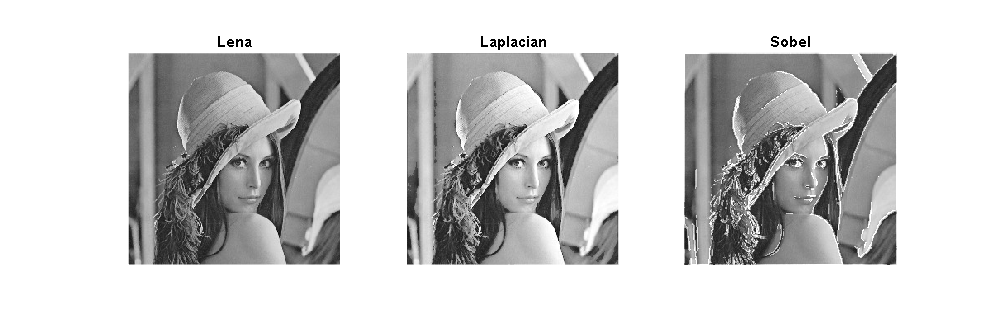

lena = struct2array(load("gray_level_lena.mat"));
vert_sobel_lena = conv2(lena,sobel_v,"same");
horz_sobel_lena = conv2(lena,sobel_h,"same");
grad_sobel_lena = sqrt(vert_sobel_lena.^2 + horz_sobel_lena.^2);
laplacian_lena = conv2(lena,laplacian,"same");
local_var_lena = conv2(lena,variance,"same");
local_var_lena = 1/9 * local_var_lena.^2;

if_edge_lena = local_var_lena>0.5 & laplacian_lena < 0.5;

figure('Position', [10 10 900 300]);
subplot(1,3,1);
imshow(lena)
colormap gray;
title("Lena")
subplot(1,3,2);
imshow(lena+0.15*if_edge_lena)
colormap gray;
title("Laplacian")
subplot(1,3,3);
imshow(lena+0.4*(grad_sobel_lena>0.8));
colormap gray;
title({"Sobel"})

### Q4

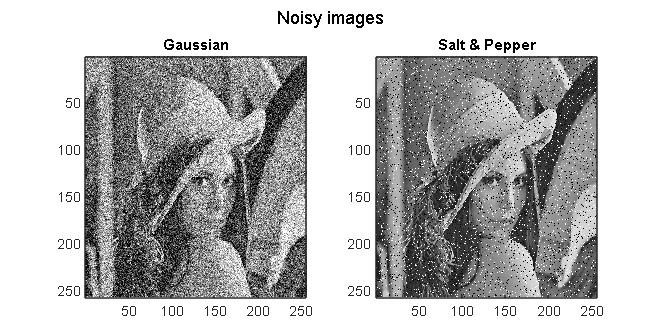

lena = struct2array(load("gray_level_lena.mat"));
std_noise = 0.05;
I_g = imnoise(lena,'gaussian',0,std_noise); 
I_sp = imnoise(lena,'salt & pepper',0.1);
figure('Position', [10 10 600 300]);
subplot(1,2,1);
imagesc(I_g)
colormap gray;
title("Gaussian")
subplot(1,2,2);
imagesc(I_sp)
colormap gray;
title("Salt & Pepper")
sgtitle("Noisy images")

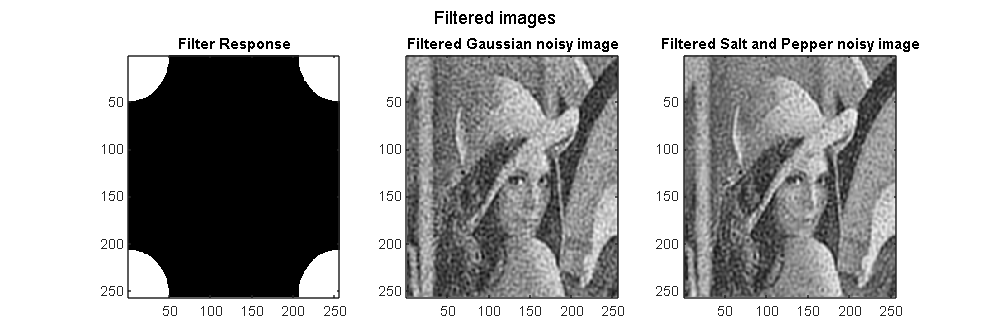

[X,Y] = meshgrid(-127:128,-127:128);
F = zeros(size(lena));
F(X.^2+Y.^2<2500) = 1;
F = fftshift(F);
filt_g = real(ifft2(fft2(I_g).*F));
filt_sp = real(ifft2(fft2(I_sp).*F));
figure('Position', [10 10 900 300]);
subplot(1,3,1);
imagesc(F)
colormap gray;
title("Filter Response")
subplot(1,3,2);
imagesc(filt_g)
colormap gray;
title("Filtered Gaussian noisy image")
subplot(1,3,3);
imagesc(filt_sp)
colormap gray;
title("Filtered Salt and Pepper noisy image")
sgtitle("Filtered images")

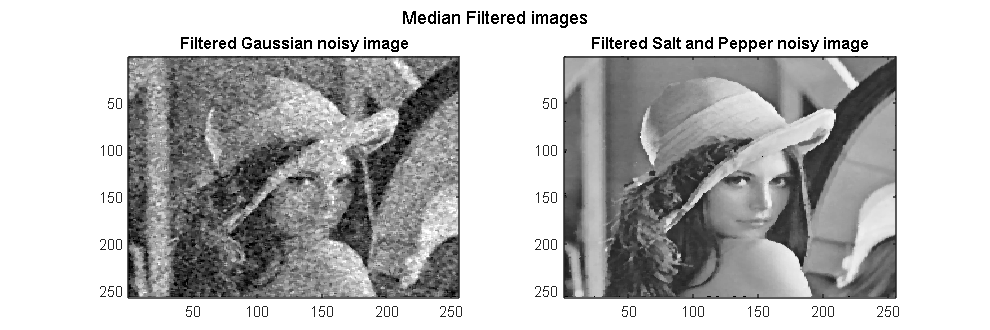

filt_g = medfilt2(I_g,[3 3]);
filt_sp = medfilt2(I_sp,[3 3]);
figure('Position', [10 10 900 300]);
subplot(1,2,1);
imagesc(filt_g)
colormap gray;
title("Filtered Gaussian noisy image")
subplot(1,2,2);
imagesc(filt_sp)
colormap gray;
title("Filtered Salt and Pepper noisy image")
sgtitle("Median Filtered images")

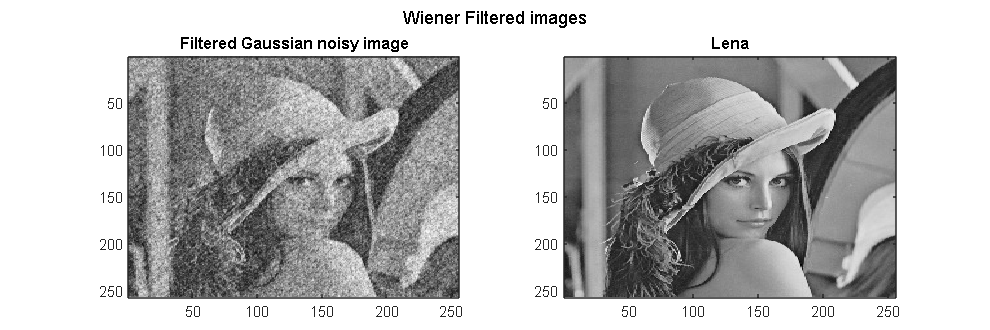

psd_lena = abs(fft2(lena)).^2/(numel(lena)); % PSD Estimation 
wiener = (1 + std_noise^2*ones(size(lena))./psd_lena).^(-1);
filt_g = (ifft2(fft2(I_g).*wiener));
figure('Position', [10 10 900 300]);
subplot(1,2,1);
imagesc(filt_g)
colormap gray;
title("Filtered Gaussian noisy image")
subplot(1,2,2);
imagesc(lena)
colormap gray;
title("Lena")
sgtitle("Wiener Filtered images")

ssim1 = ssim(I_g,lena) 

ssim1 = 0.1644

ssim2 = ssim(filt_g,lena)

ssim2 = 0.3254

### Q5

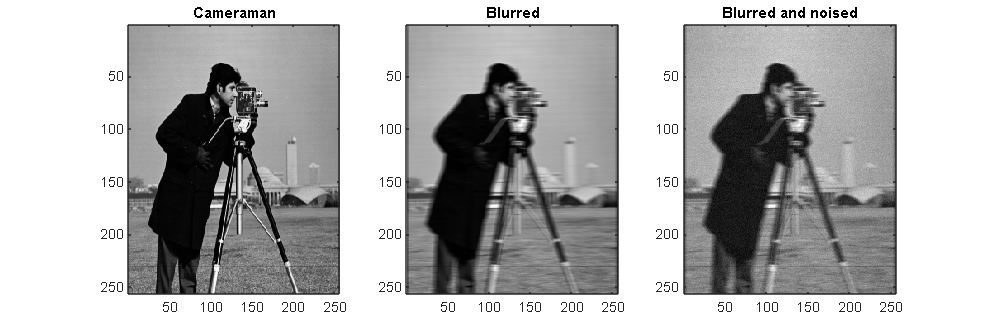

I = im2double(imread('cameraman.tif'));
h = ones(1,8);
blurred = conv2(I,h,"same");
noised = blurred + 0.2*randn(size(blurred));
figure('Position', [10 10 900 300]);
subplot(1,3,1);
imagesc(I)
colormap gray;
title("Cameraman")
subplot(1,3,2);
imagesc(blurred)
colormap gray;
title("Blurred")
subplot(1,3,3);
imagesc(noised)
colormap gray;
title("Blurred and noised")

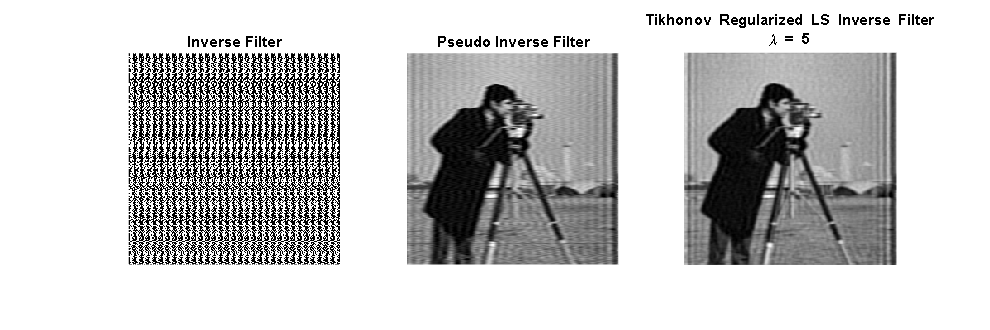

H = fft2(h,size(I,1),size(I,2));
H(H == 0) = 1e-10;
I_f = fft2(noised);
filtered = ifft2(I_f./H);
pseudo_inv_filter = zeros(size(H));
threshold = 2;
pseudo_inv_filter(abs(H)>=threshold) = H(abs(H)>=threshold).^(-1);
pseudo_inv_filter(abs(H)<threshold) = 0;
pseudo_filtered = ifft2(I_f.*pseudo_inv_filter);
lap_filter = fft2(laplacian,size(H,1),size(H,2));
lambda = 5;
tik_filter = conj(H) ./ (abs(H).^2 + lambda*(abs(lap_filter).^2));
tik_filtered = ifft2(I_f.*tik_filter);
figure('Position', [10 10 900 300]);
subplot(1,3,1);
imshow(filtered)
colormap gray;
title("Inverse Filter")
subplot(1,3,2);
imshow(pseudo_filtered)
colormap gray;
title("Pseudo Inverse Filter")
subplot(1,3,3);
imshow(tik_filtered)
colormap gray;
title({"Tikhonov Regularized LS Inverse Filter",['\lambda = ',num2str(lambda)]})